# Demo Dynamic Systems and Control Theory

Demo to show the basics of a dynamic system, closed loop, resonances and filters.

Every parameter can be changed to see the effects. The nominal ones are for show.

clear
close all
clc


## 1. Simulate 2nd order dynamic system

Choose frequency and damping for this system:

freq_sys1 = 10; % [Hz]
zeta_sys1 = 0.1;

sys_dyn1 = make_dynsys_poles(freq_sys1, zeta_sys1);

Choose a set of frequencies to simulate the responce to and plot the inpot and output on the same plot for comparison.

Note: the time of simulation will be different for different frequencies. The simulation runs (hard coded) for 10 cycles.

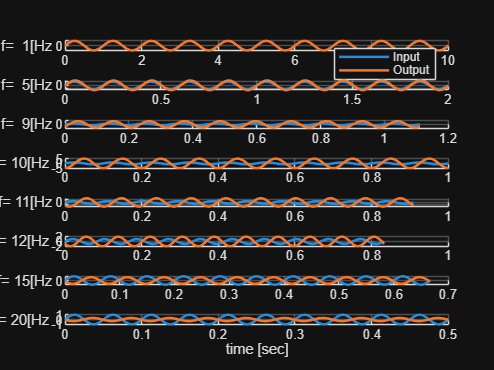

freq_4sim = [1 5 9 10 11 12 15 20];
len_f = length(freq_4sim);

fid_sin_resp = figure;

for indf = 1:len_f
    inp.f = freq_4sim(indf);
    sim_out = simulate_sin_inp_an(inp, sys_dyn1);

    % plot excitation and responce
    subplot(len_f, 1, indf); hold on
    plot(sim_out.t, sim_out.u, LineWidth=1.5, DisplayName='Input')
    plot(sim_out.t, sim_out.y, LineWidth=1.5, DisplayName='Output')
    grid on
    ylbl = sprintf('f=%3.0f[Hz', freq_4sim(indf));
    ylabel(ylbl, Rotation=0)
end
xlabel('time [sec]')
subplot(len_f,1,1)
legend show

Add bode plot for the simple system

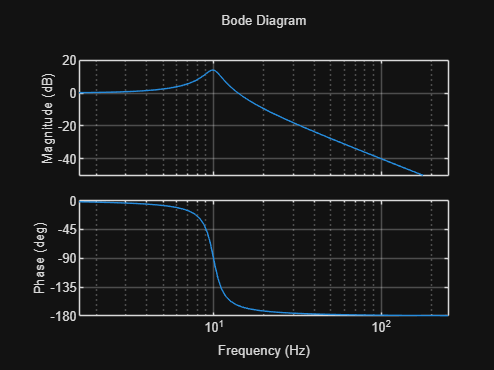


figure
bdopts = bodeoptions;
bdopts.FreqUnits = 'Hz';
bdopts.Grid = 'on';
bodeplot(sys_dyn1, bdopts)

## 2. System with resonance - 4th order (zeros at high frequencies)

Choose low frequency for the main dynamics and high frequency for the resonance. The main dynamics damping should be average the resonance - very low.

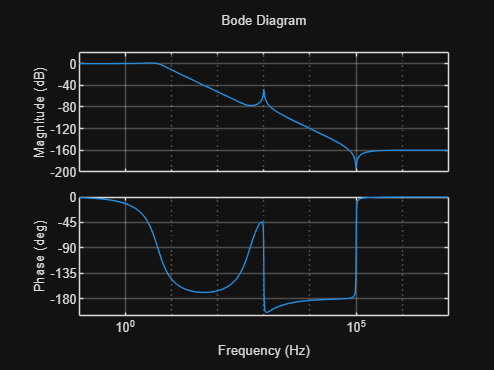

freq_sys21 = 5; % [Hz]
zeta_sys21 = 0.5; % damping

freq_sys22 = 1000; % [Hz]
zeta_sys22 = 0.01; % damping

sys_dyn21 = make_dynsys_wzeros(freq_sys21, zeta_sys21);
sys_dyn22 = make_dynsys_wzeros(freq_sys22, zeta_sys22);

sys_dyn2 = sys_dyn21 * sys_dyn22;

figure
bodeplot(sys_dyn2, bdopts)


[GM_ol, PM_ol, Wcg_ol, Wcp_ol] = margin(sys_dyn2);


## 3. Closed loop behavior

Use simple PID inline to close the loop on the system with resonance

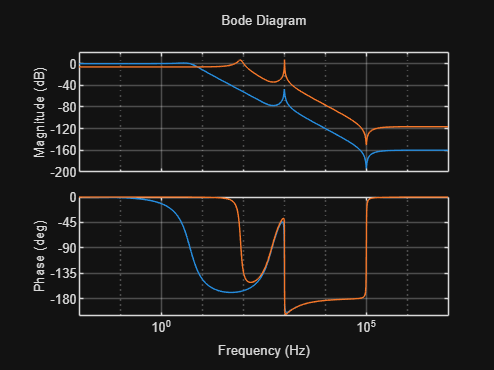

G = sys_dyn2; % Define Plant
H = 2;        % Define the feedback tf

Kp = 150; % Proportional gain
Ki = 150; % Integrator gain
Kd = 0;   % Differential gain (None)
Tf = 0;
C_PI = pid(Kp, Ki, Kd, Tf); % PI controller

sys_cl2 = feedback(C_PI*G, H); % Closed loop system

figure
bodeplot(sys_dyn2, sys_cl2, bdopts)


[GM_cl, PM_cl, Wcg_cl, Wcp_cl] = margin(sys_cl2);

## 4. Low pass filter

Added in the forward part of the loop, inside the controller. 

The LPF is the same as the second order system with poles only.

freq_lpf = 10; % [Hz]
zeta_lpf = 0.1;

sys_lpf = make_dynsys_poles(freq_lpf, zeta_lpf);

figure
bodeplot(sys_lpf, bdopts)

sys_cl2_wlpf = feedback(C_PI*sys_lpf*G, H); % Closed loop system with lpf in the controller

figure
bodeplot(sys_dyn2, sys_cl2, sys_cl2_wlpf, bdopts)
legend show


## Functions

### 1. make_dynsys_poles creates a second order low pass filter. Only the poles are used and the gain is normalized to 1.

function sys = make_dynsys_poles(freq, zeta)

omega = 2*pi*freq;

num = [omega^2];
den = [1, 2*zeta*omega, omega^2];

sys = tf(num, den);

end


### 2. Simulate dynamic behavior of a system in response to sinus excitation

function out = simulate_sin_inp_an(inp, sys_dyn)

f = inp.f;
w = 2*pi*f;
T = 1/f;

H = freqresp(sys_dyn,w);
amp = abs(H); phase=angle(H);

% NOTE: parameterize this
t_max = T*10; %Time of simulation will be exitation for 10 cycles
t = 0:0.0005:t_max;

u = sin(w*t);           % excitation signal
y = amp*sin(w*t+phase); % responce signal

out.t = t;
out.u = u;
out.y = y;

end

### 3. Create system with poles and zeros, zero frequency multiplied by a factor

function sys = make_dynsys_wzeros(freq, zeta)

omega = 2*pi*freq;

factorz = 100; %NOTE: parametrise
k = 1/factorz/factorz;
omegaz = omega*factorz;

num = k*[1 2*zeta*omegaz omegaz^2];
den = [1, 2*zeta*omega, omega^2];

sys = tf(num, den);

end